# PLV Power Analysis

How many spikes at a preferred phase does it take to detect a non-zero PLV?

Simulated spikes that have von Mises tuning for the phase of a tACS signal, and investigated how the power to detect an effect at a given significance level increases with the von Mises kappa. 

By reading off which PLV value has good power to be detected, we also get an estimate of the % of spikes that artifacts would have to cause to result in incorrect conlcusions about entrainment. 

Based on the simulations below, for 2 minutes of data with 10 Hz firing rate, this is 5-10%. With longer recordings, this shifts below 5%.

In other words, if artifacts result in more than 5% of "artifact spikes" in a 180 phase bin then they are likely to affect conclusions about entrainment. Or, conversely, artifact removal has to be better than this to get reliable results.

## Set Parameters

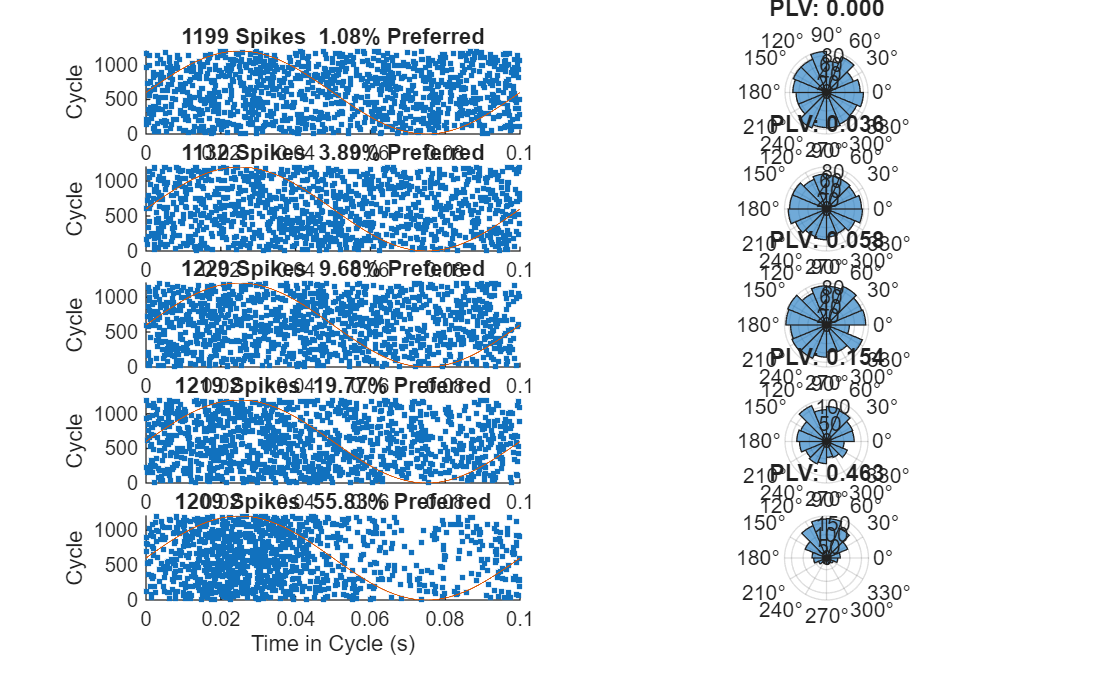

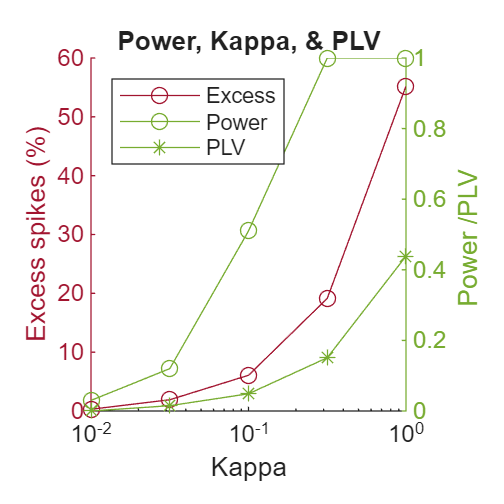

o=artSim;

o.duration              = 60*2; % [s]  Johnson et al 2 min, Krause et al up to 40 min.
o.spikeRate             = 10;  % [1/s]  Johnson et al , Krause et al 10 Hz
o.spikePeak             = 100e-6; % [muV]
o.recordingSamplingRate = 30e3;
o.lfpAmplitude          = 1;
o.lfpFrequency          = 10;
o.preferredPhase        = 0.5*pi;
o.poisson               = true;


nrPhaseBins = 16;  % Visualization only
kappas      = 10.^(-2:0.5:0); % Investigate this range of vonMises kappa
nrKappas    = numel(kappas);
nrRepeats   = 100;     % Repeat each set this number of times for a power estimate
nrBootstrap = 100;   % Bootstrap PPC for signficance test.
significanceLevel =0.05; % Alpha level


f = figure;
set(f,'Name','PLVKappaExample');
R=nrKappas;C= 2;
peakVsTrough = nan(nrRepeats,nrKappas);  % Percentage excess spikes in the 180 degree near preferred.
ppcValue = nan(nrRepeats,nrKappas);      % Computed PPC
pValue =nan(nrRepeats,nrKappas);         % p-Value for PPC>0
t = o.tSimulate;

for i=1:nrKappas
    o.synchrony = kappas(i);
    for j= 1:nrRepeats
        o.simLfp;
        o.simSpikes;
        [ppcValue(j,i),pValue(j,i)] = ppc(o.ixSpike,o.phaseLfp,nrBootstrap);

        inPreferredHalf = sin(angle(exp(1i*(o.preferredPhase-0.5*pi)).*exp(1i*o.phaseLfp(o.ixSpike))))>0;
        peakVsTrough(j,i) = 100*(sum(inPreferredHalf)-sum(~inPreferredHalf))/numel(inPreferredHalf);

        if j==1
            % Show the first repeat as an example
            subplot(R,C,(i-1)*C+1)
            hold on
            % Raster
            oneCycle = 1./o.lfpFrequency;
            nrCycles= o.duration*o.lfpFrequency;
            % Show a "raster"- as all cycles are the same, we can just put the tick at t a
            % random y-level (i.e. a cycle)
            plot(mod(t(o.ixSpike),oneCycle),randi(nrCycles,numel(o.ixSpike),1),'.');
            hold on;
            plot(t(t<oneCycle),0.5*nrCycles*(1+o.lfp(t<oneCycle)))
            title(sprintf('%d Spikes  %3.2f%% Preferred',numel(o.ixSpike),peakVsTrough(j,i)))
            xlim ([0 oneCycle])
            ylim ([0 nrCycles])
            xlabel 'Time in Cycle (s)'
            ylabel 'Cycle'

             subplot(R,C,(i-1)*C+2)       
            % Polar
            polarhistogram(o.phaseLfp(o.ixSpike),nrPhaseBins)
            title(sprintf('PLV: %3.3f',sqrt(max(0,ppcValue(j,i)))))
        end
    end
end

## Summarize

fig('Name','PLVKappa','nrRows',1,'nrCols',1);
yyaxis left
ax =gca;
h1= plot(kappas,mean(peakVsTrough),'Color',ax.YColor, 'LineStyle','-','Marker','o');

ylabel 'Excess spikes (%)'
hold on
yyaxis right
ax =gca;
h2= plot(kappas,mean(pValue<significanceLevel),'Color',ax.YColor, 'LineStyle','-','Marker','o');
hold on
h3 = plot(kappas,sqrt(max(0,mean(ppcValue))),'Color',ax.YColor, 'LineStyle','-','Marker','*');
ylabel 'Power /PLV '
legend([h1 h2 h3], 'Excess','Power','PLV','Location','NorthWest')
xlabel 'Kappa'
set(gca,'XScale','Log')
ylim([0 1])
title ' Power, Kappa, & PLV '

